# Object Detection Using YOLO v2 Deep Learning

Kelompok 01 - Pemrosesan Sinyal Multimedia 02

Aidan Azkafaro Deson - 2006528862

M. Taqiy Nur Furqon - 2006468900

Program ini akan menjelaskan tentang penggunaan YOLO v2 untuk Object Detection pada Matlab.

Beberapa toolbox yang diperlukan pada program ini:

- Computer Vision Toolbox

- Deep Learning Toolbox

- Deep Learning Toolbox Model for ResNet-50 Network

- Image Processing Toolbox

## Download Pretrained Detector

Mendownload pretrained detector untuk menjalankan program tanpa melakukan training. Jika ingin melakukan training kepada detector, set variabel `doTraining menjadi true.`

doTraining = false;
if ~doTraining && ~exist('yolov2ResNet50VehicleExample_19b.mat','file')    
    disp('Downloading pretrained detector (98 MB)...');
    pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/yolov2ResNet50VehicleExample_19b.mat';
    websave('yolov2ResNet50VehicleExample_19b.mat',pretrainedURL);
end

## Load Dataset

unzip vehicleDatasetImages.zip
data = load('vehicleDatasetGroundTruth.mat');
vehicleDataset = data.vehicleDataset;

Data dari foto kendaraan disimpan pada tabel berisi dua kolom, di mana kolom pertama berisi path ke masing-masing gambarnya, sedangkan kolom kedua adalah array berisi koordinat bounding box dari masing-masing gambar.

% Menampilkan beberapa data kendaraan
vehicleDataset(1:4,:)

ans = 4×2 table
              imageFilename                   vehicle     
    _________________________________    _________________

    {'vehicleImages/image_00001.jpg'}    {[220 136 35 28]}
    {'vehicleImages/image_00002.jpg'}    {[175 126 61 45]}
    {'vehicleImages/image_00003.jpg'}    {[108 120 45 33]}
    {'vehicleImages/image_00004.jpg'}    {[124 112 38 36]}


% Menambahkan alamat lengkap dari folder data kendaraan
vehicleDataset.imageFilename = fullfile(pwd,vehicleDataset.imageFilename);

Membagi dataset menjadi training, valildation, dan test. 

60% -> training

10% -> validation

30% -> testing

rng(0);
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = vehicleDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = vehicleDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = vehicleDataset(shuffledIndices(testIdx),:);

Menggunakan imageDatastore dan boxLabelDatastore untuk membuat penyimpanan data yang menyimpan data gambar dan labelnya saat training dan evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'vehicle'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'vehicle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'vehicle'));

Menggabungkan image dan data box label.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Menampilkan salah satu gambar training serta box label nya.

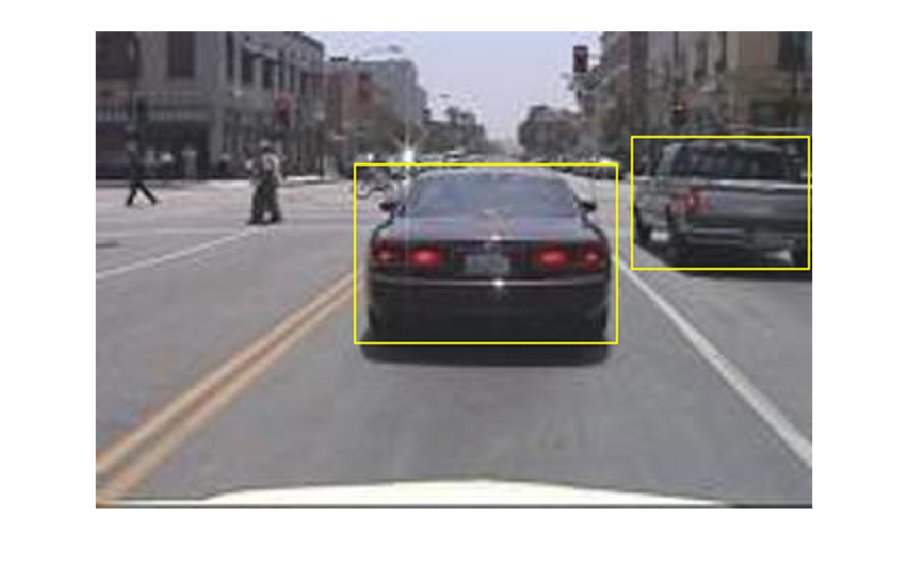

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Membuat Jaringan Object Detection YOLO v2 

Jaringan object detection dari Yolo v2 terdiri dari dua sub jaringan yaitu jaringan feature extraction yang diikuti oleh jaringan deteksi. Untuk jaringan feature extraction pada umumnya merupakan sebuah model CNN pretrained. Pada contoh ini, digunakan model ResNet-50 untuk proses feature extraction. Opsi lain dapat menggunakan model seperti MobileNet v2 ataupun ResNet-18 tergantung dari kebutuhan implementasinya. 

Gunakan fungsi [`yolov2Layers`](docid:vision_ref#mw_b1e7b78e-2ce3-4d2f-ad8d-f5acd725f170) untuk membuat jaringan object detection YOLO v2 yang secara otomatis memberikan jaringan pretrained ResNet-50 untuk feature extraction. Beberapa input parameter yang harus diberikan ke jaringan YOLO v2 adalah: 

- Network input size

- Anchor boxes

- Feature extraction network 

Pertama, tentukan ukuran input jaringan dan jumlah kelas. Saat memilih ukuran input jaringan, pertimbangkan ukuran minimum yang dibutuhkan oleh jaringan itu sendiri, ukuran gambar latihan, dan biaya komputasi yang diperlukan untuk memproses data pada ukuran yang dipilih. Jika memungkinkan, pilih ukuran input jaringan yang mendekati ukuran gambar latihan dan lebih besar dari ukuran input yang dibutuhkan oleh jaringan. Untuk mengurangi biaya komputasi saat menjalankan contoh ini, tentukan ukuran input jaringan [224 224 3], yang merupakan ukuran minimum yang dibutuhkan untuk menjalankan jaringan.

inputSize = [224 224 3];

Set jumlah kelas objek yang akan dideteksi.

numClasses = width(vehicleDataset)-1;

Note that the training images used in this example are bigger than 224-by-224 and vary in size, so you must resize the images in a preprocessing step prior to training.

Gambar-gambar yang akan digunakan pada proses training lebih besar dari ukuran input jaringan yaitu 224x224, sehingga kita perlu melakukan tahap preprocessing untuk me-resize gambar-gambar tersebut sebelum masuk tahap training.

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 7;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =     41    33
   156   128
    76    72
   139   120
    33    23
    60    60
   100    93


meanIoU = 0.8589

Load model pretrained ResNet-50.

featureExtractionNetwork = resnet50;

Menggunakan `'activation_40_relu'` sebagai layer feature extraction. Layer ini akan menghasilkan feature maps yang di-downsample atau dikurangin ukurannya sebanyak faktor 16. Dengan adanya downsampling ini, akan terjadi trade-off yang baik antara resolusi spasial dan kekuatan fitur yang diekstraksi. 

featureLayer = 'activation_40_relu'; 

Membuat jaringan YOLO v2 untuk melakukan object detection.

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

## Data Augmentation

Data augmentation digunakan untuk meningkatkan akurasi jaringan dengan secara acak mentransformasi data asli selama pelatihan. Dengan menggunakan data augmentation, Anda dapat menambahkan variasi lebih banyak ke data pelatihan tanpa harus benar-benar meningkatkan jumlah sampel pelatihan.

augmentedTrainingData = transform(trainingData,@augmentData);

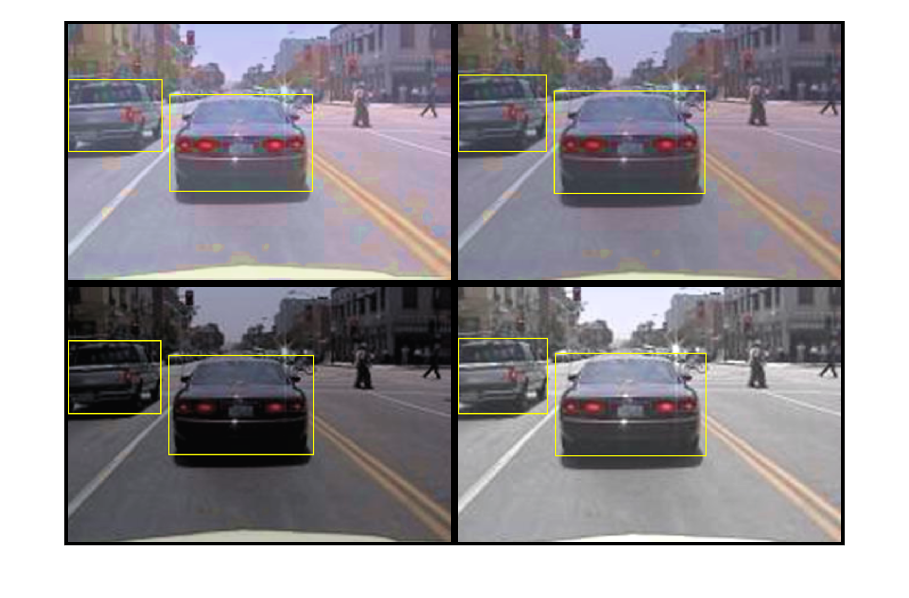

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

## Preprocess Training Data

Menerapkan Preprocessing juga terhadap augmentedTrainingData

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
preprocessedValidationData = transform(validationData,@(data)preprocessData(data,inputSize));

Membaca data hasil preprocessing

data = read(preprocessedTrainingData);

Menampilkan gambar beserta bounding boxes-nya

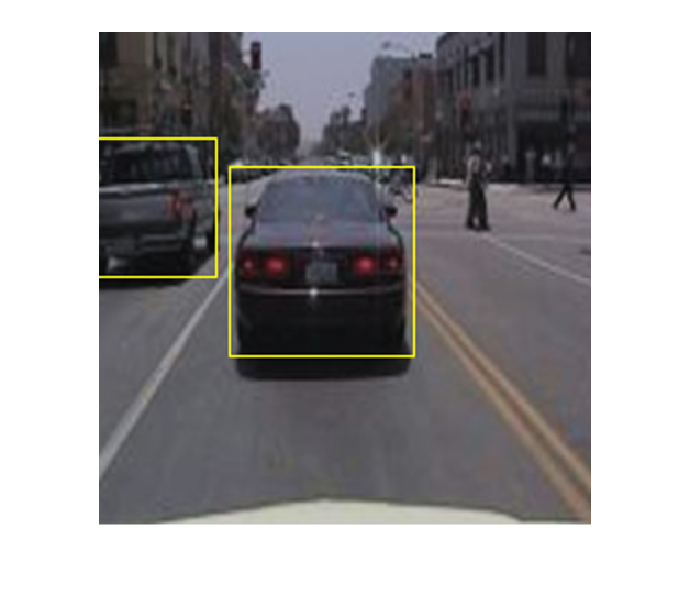

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Train YOLO v2 Object Detector

Menspesifikasi opsi jaringan untuk training.

options = trainingOptions('sgdm', ...
        'MiniBatchSize',16, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',20, ... 
        'CheckpointPath',tempdir, ...
        'ValidationData',preprocessedValidationData);

Use [`trainYOLOv2ObjectDetector`](docid:vision_ref#mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) function to train YOLO v2 object detector if `doTraining` is true. Otherwise, load the pretrained network.

Kode di bawah akan melakukan training apabila `doTraining` bernilai true. Jika tidak, gunakan pretrained detector.

if doTraining       
    % Train the YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);
else
    % Load pretrained detector for the example.
    pretrained = load('yolov2ResNet50VehicleExample_19b.mat');
    detector = pretrained.detector;
end


Load test image 

t_img = imread('highway.png');
t_img = imresize(t_img, inputSize(1:2));
[bboxes,scores] = detect(detector,t_img);

Menampilkan hasilnya

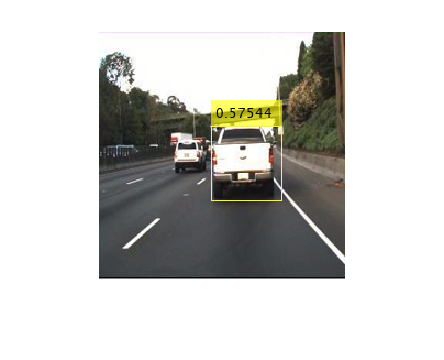

t_img = insertObjectAnnotation(t_img,'rectangle',bboxes,scores);
figure
imshow(t_img)

## Evaluate Detector Using Test Set

Pada section ini, kita akan mengevaluasi performa object detector pada test set. Beberapa metric yang digunakan adalah average precision dan log-average miss rate. 

preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));

Menjalankan detector pada test data

detectionResults = detect(detector, preprocessedTestData);

Mengevaluasi detector menggunakan metric average precision

[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedTestData);

Kurva precision/recall (PR) memperlihatkan seberapa akurat detektor dalam tingkat recall yang berbeda-beda. Nilai precision yang ideal adalah 1 pada semua tingkat recall. Penggunaan lebih banyak data dapat membantu meningkatkan nilai average precision, tapi mungkin membutuhkan waktu training yang lebih lama. 

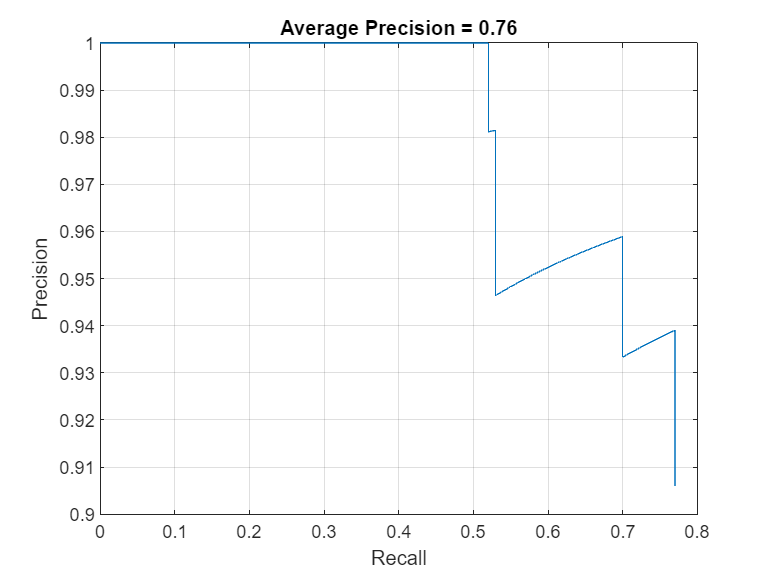

figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',ap))

## References

[1] Redmon, Joseph, and Ali Farhadi. “YOLO9000: Better, Faster, Stronger.” In *2017 IEEE Conference on Computer Vision and Pattern Recognition (CVPR)*, 6517–25. Honolulu, HI: IEEE, 2017. [https://doi.org/10.1109/CVPR.2017.690.](https://doi.org/10.1109/CVPR.2017.690.)

[2] “Object detection using Yolo V2 Deep Learning,” Object Detection Using YOLO v2 Deep Learning - MATLAB & Simulink, https://www.mathworks.com/help/vision/ug/train-an-object-detector-using-you-only-look-once.html.